# Modsim Project 2: How to Save Energy in the Winter

## Question

In the winter, people are often told to turn the heat down/off when they leave the house to save energy. However, there is also an argument that leaving the heat on when you leave is more efficient.  This model will seek to explain if there are any scenarios were leaving the heat on could be more energy efficient than turning it off when leaving the house for some amount of time.  Answering this question is important because it could resolve a potential spread of misinformation. In addition, it might help homeowners make more energy conscious decisions about their heating which would benefit their wallets and the environment.

**Learning Objectives: **As a result of writing this notebook, we (the authors) hope to:

- Learn how to create a good modeling question

- Understand best practices in structuring a thermodynamic model

- Practice generating ODEs for a modeling question

## Methodology

### Diagram

To answer the modeling question, a simple house was defined as follows:

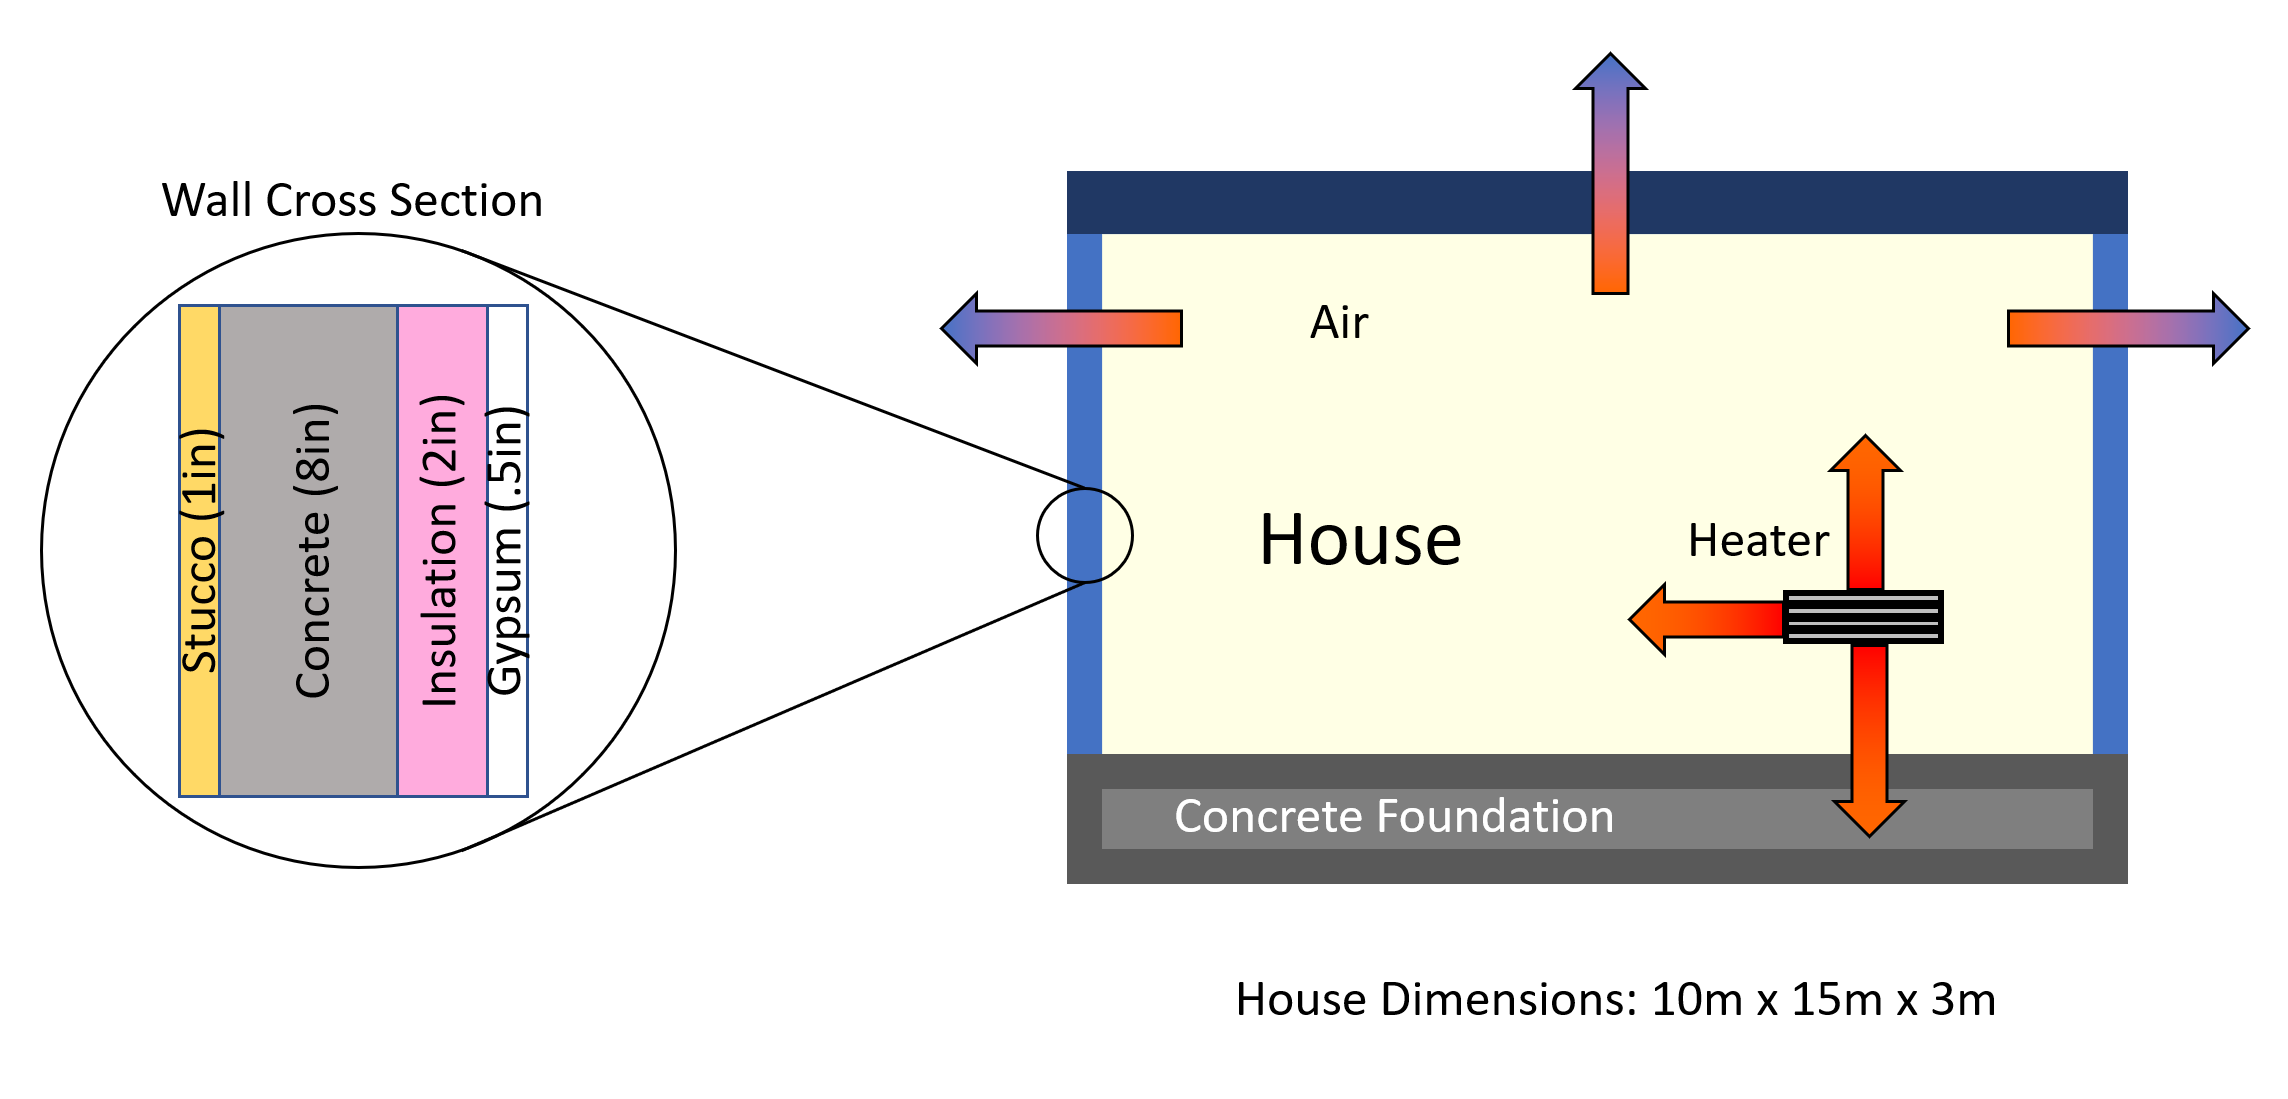

The house was modeled after an "average" house in Massachusetts. The house used in this model is a house of width 10 meters, length 15 meters, and hieght 3 meters, giving the house a square meters value slightly lower than the average house in MA (162 m^2).

The house walls were modeled after the standard office building as according to the Department of Energy (citation), and were composed of gipsum, fiber batting, concrete, and stucco. We treated the only important insulating material in the roof (attic) as fiber batting; thus the roof is effectively made of only fiber batting. The floor is made out of concrete and has a thickness that is standard for residential construction.

In the model, we treated the thermal mass of the house as being composed of the floor and the air inside the house.

House Parameters

- **House Size: **as previously stated, the house is a 10x15x3 meter rectangular prism.

- **Wall Composition: **from the inside to outside, the walls are composed of 0.5 in gipsum, 2 in fiber batt, 8 in concrete, and 1 in stucco.

- **Roof Composition: **the roof is composed of 16 in fiber batt.

- **Floor Composition: **the floor is composd of 4 in concrete.

General Parameters

- **Ideal House Temperature: **the ideal temperature at which the house's residents in our scenario would like to keep the temperature. Set at 22 degrees C, which is a generally universal comfortable temperature.

- **Lowered House Temperature: **the temperature at which the house's residents would lower the temperature while gone. Set at 13 degrees C.

- **Ambient Temperature Minimum: **the minimum ambient (outside) temperature. As we are modeling the house in a Boston winter, a value of -6 C is reasonable and matches historical averages for winter (Wikipedia).

- **Ambient Temperature Maximum: **the amount that the ambient temperature increases throughout the day, as it gets warmer. 2 C, is a reasonable value.

- **Heater Power: **most homes in America use a gas powered forced air furnace for heat. These appliances generally range in power from 15,000 to 35,000 kWh. We chose 25,000 kWh as the heater used in the house.

Scenario Parameters

- **Time Of Day That Resident Leaves House: **assumed in all scenarios to be 9 AM, which is a normal time to leave for work.

- **Length Time Resident Is Gone From House: **the parameter that we're varying

- **Simulation Length: **24 hours. Each simulation is kept at the same length to ensure that the energy consputions vlaues are dirrectly comparable.

### Stock and Flow

To further develop the model, a stock and flow diagram of a house was created.  In this model, the stock is the internal energy of the house. Energy flows in to the house from a heater and flows out of the house though conduction through the walls and roof. When the heater is on, it adds energy at a constant rate (in watts) and when it is off, no heat is added. 

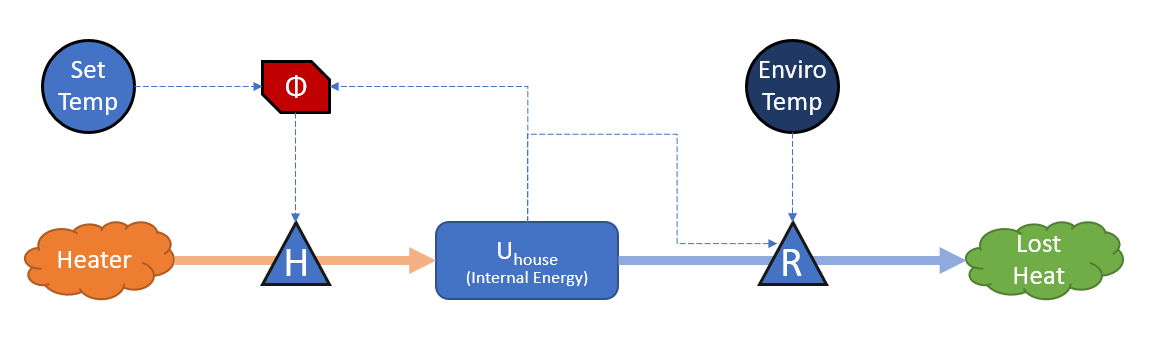

Flows in

- Gas Furnace Heating System: This is a forced input which depends on whether the house's current temperature is below the ideal temperature.

Flows out

- Conduction through walls and roof

While we are not considering the effects of solar energy flowing into the system, we are varying the ambient temperature as a function of the time of day.  We employed a simple model built by Donald et al. that uses a type III Pearson distribution. A link to the paper describing the model can be found [here](https://mathscinotes.com/wp-content/uploads/2012/12/dailytempvariation.pdf).

### Mathematical Model

From the stock and flow diagram, the following differential equation is generated.


$$\frac{dU}{dt} = H\Phi - \frac{\Delta T}{R_{tot}}$$


 Where:

- $U$ is the internal energy of the house

- $H$ is the wattage of the heater

- $\Phi$ is a logical value indicating if the heater is on or off

- $\Delta T$ is the temperature difference between the house and the environment

- $R_{tot}$ is the total conductive resistivity of the house walls and roof

To calculate if the heater is on or off ($\Phi$), the model uses a discrete “overshoot and undershoot control band” which is commonly found in household thermostats. In this control algorithm, the heater overshoots the temperature set point by some buffer value and will not turn back on again until the heat in the house has dropped below the setpoint minus the buffer value. This causes the temperature of the house to oscillate around the set temperature and allows the heater to turn on less frequently.

This control system will be maintained in all scenarios while the set temperature will be varied to reflect keeping the heater on vs. turning it down or off. A parameter sweep can then be carried out to probe the effects of the different parameters in the model and compare the efficiencies of the scenarios.

To calculate the total energy ($E$) used by the heater in order to assess each scenario, the model also tracks $\frac{dE}{dt} = H\Phi$

We decided to use Euler’s method to solve the system due to its simplicity and flexibility when incorporating multiple parameters such as heater state and environmental temperature.

### Assumptions

In the model, there are several assumptions that are made.  Firstly, the house being modeled is very simple and it does not contain any internal walls, furniture, appliance, etc. Therefore, the thermal mass of the house can only be a crude estimate.  However, because this generalization will affect both scenarios, the model should still make informative relative comparisons.

In addition, all the house’s internal energy is modeled by a single stock. In other words, we are assuming that the system is quasi static. This is reasonable because the rate at which the heater heats the air is likely slower than the rate the air heats the solid material in the house. 

### Global Variables/Conversions

global k_to_c hours_to_seconds effective_off_temp ideal_temp freezing_temp heater_power;
k_to_c = 273;
hours_to_seconds = 60*60;
effective_off_temp = -10 + k_to_c;
ideal_temp = 22 + k_to_c; % 22
freezing_temp = 0 + k_to_c;
down_temp = 19 + k_to_c; % 13
heater_power = 25000; % watts, Heater power

### **Verification and Validation**

To verify the implementation of the model, a test scenario was generated where the house is subjected to changing daily temperatures for 3 days with no heater. The initial house temperature was 22 C. The results of this experiment are presented in the following figure. 

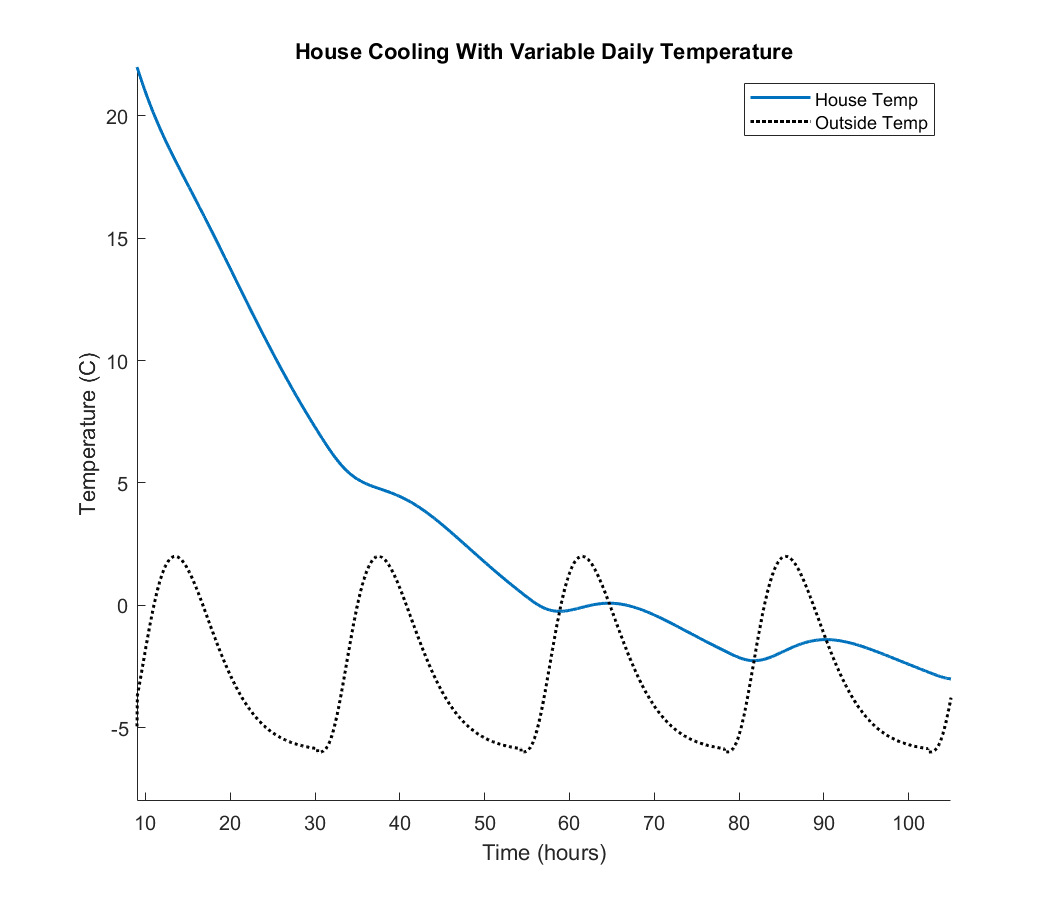

%define evaluation matrix with times and assiocated set_temps
%the model will use this to define the time-step and evaluation range

dt = 10; %seconds
time_range = 9*hours_to_seconds:dt:(96+9)*hours_to_seconds;   %create a time array that starts at 9AM night and run for 4 days
temp_range = 250*ones(size(time_range));                     %create a temp array that is the same size as the time array

%concatenate evalution matric
evaluation_matrix = [time_range ; temp_range];

%define initial house temp
house_temp_0 = 22 + k_to_c;

%run simulation
[temperature, ~, ~, outside_temp] = house_simulation(evaluation_matrix, house_temp_0);

%plot results
plot1

As expected, this plot shows that the house temperature drops when the external temperature is cooler and rises when the external temperature is warmer. In addition, the lag between peaks in internal and external temperature are confimation of the presence of a significant thermal mass in the house.

In the next test, the heater control loop was enabled.  The house is initially at 15 C while the set temperature is set to 22 C for 6 hours, then the set temperature is turned "off" for 6 hours, finally the set temp is restored to 22 C for yet another 6 hours. "Off" is defined as -10 C which is far below the house temperature and minimum external temperature, so we can confidently assume that the house will never reach this temperature, meaning that the thermostat is effectively off.

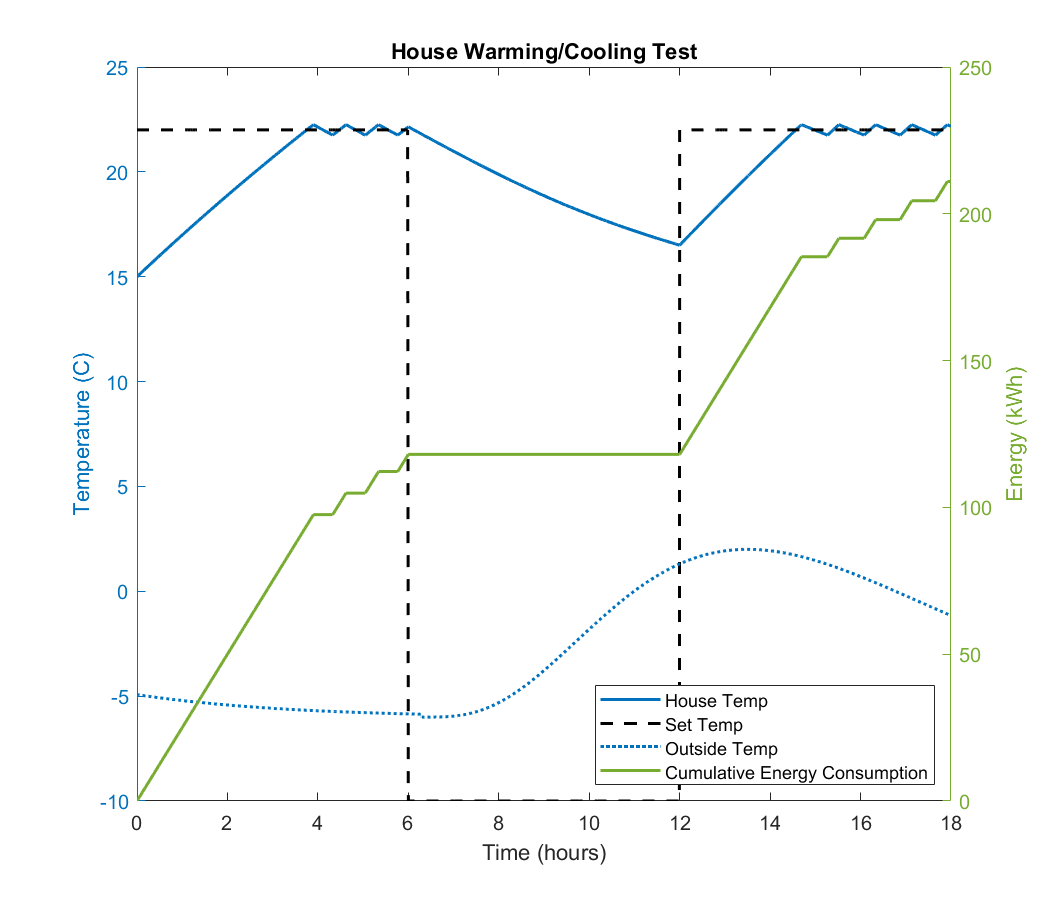

%define evaluation matrix with times and assiocated set_temps
%the model will use this to define the time-step and evaluation range

dt = 1; %seconds

time_range = 0:dt:18*hours_to_seconds;  %starts at 12AM and runs for 18 hours
temp_range = ones(size(time_range));    %make empty temp matrix of same size

%fill temp matrix
temp_range(1:6*hours_to_seconds/dt) = 22 + k_to_c;
temp_range(6*hours_to_seconds/dt:12*hours_to_seconds/dt) = effective_off_temp;
temp_range(12*hours_to_seconds/dt:end) = 22 + k_to_c;

%concatenate evalution matric
evaluation_matrix = [time_range ; temp_range];

%initial house temp
house_temp_0 = 15 + k_to_c;

%run simulation
[temperature, energy_consumption, on_time, outside_temp] = house_simulation(evaluation_matrix, house_temp_0);

%plot results
plotDefault(evaluation_matrix(2,:), time_range, temperature, energy_consumption, outside_temp, "House Warming/Cooling Test", [-10 25])

dispOnTime(on_time)

Total on time: 8.4406hours


This graph shows the expected behavior of the model and helps to both verify and validate the model as a whole.

One final verification is to multiply the wattage of the heater by the total on time. This value should match the total energy consumption at the end of the run.

on_time * heater_power == energy_consumption(end)

ans = logical
   1

## Results

### Parameter Sweep

To answer the modeling question, a sweep is performed for three different scenarios: leaving the `set_temp` constant at 22C (leaving the heat on), turning the `set_temp` down to 13 C (turning the heat down), and turning the `set_temp` “off” (turning the heat off).  The sweeping parameter is the time “away-from-home” ranging from 0 hours to 24 hours in 15 minute steps.  

In each run, the house is initially at 22C. Each run starts at 9AM when the person leaves the house and sets the `set_temp` to either 22C, 13C, or “off”.  The set_temp remains at that value for the duration of the away-from-home period (0-24 hours) after which the `set_temp` is set to 22C for the remainder of the run.

The following plot shows the time away-from-home compared to the energy consumed in the run for each of the three scenarios.

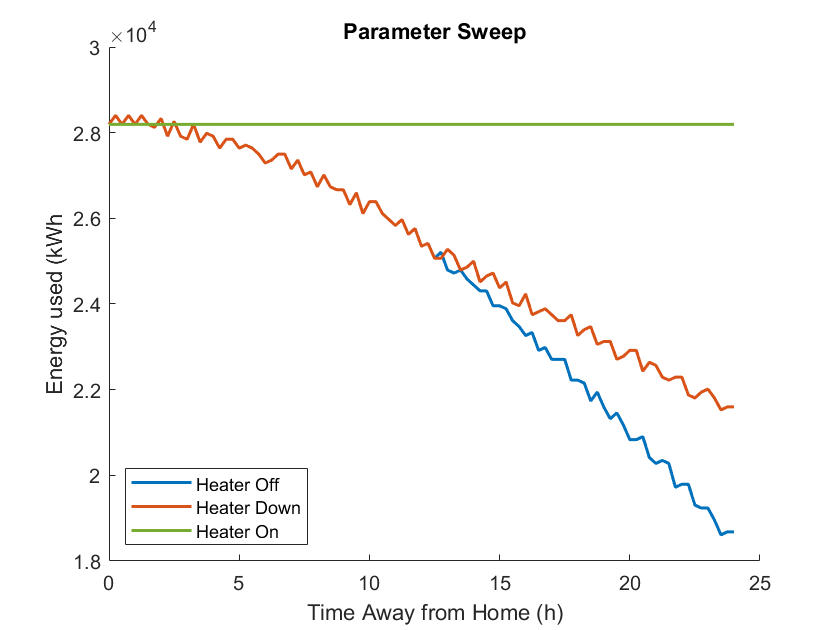

dt = 100; %seconds
time_range = 9*hours_to_seconds:dt:(24+9+8)*hours_to_seconds;
temp_range = ones(size(time_range));

sweep_range = 0:0.25:24;  %hours

sweep

## Interpretation

The results of the parameter sweep show that it was never more efficient to leave the heat on when leaving the house vs. turning the heat down or off. The jaggedness of the lines is a direct result of the thermostat control algorithm. By making the temperature threshold smaller (making the heater turn on and off more frequently) the graphs become increasingly smooth.

We also tried changing the time when the individual leaves the house (9AM vs 7AM) and found that this did not change the results significantly.

The “heater-off” and heater-down” lines are coincident for the first few hours but diverge at the moment when the house reaches the lower set temperature. From the first verification graph, we see that it takes the house 12 hours to cool from 22C to 13C which is consistent with the location that the two curves diverge.